# Make Color Maps

author:崔星星

email: cuixingxing150@gmail.com

date:2025.3.30

This live script is used to create a color array that can be directly used in the MATLAB environment, and finally saves it as 'colormapData.mat'.

% Reference Color scheme: https://yeun.github.io/open-color/
Gray = [
"#f8f9fa"
"#f1f3f5"
"#e9ecef"
"#dee2e6"
"#ced4da"
"#adb5bd"
"#868e96"
"#495057"
"#343a40"
"#212529"];

Red = [
"#fff5f5"
"#ffe3e3"
"#ffc9c9"
"#ffa8a8"
"#ff8787"
"#ff6b6b"
"#fa5252"
"#f03e3e"
"#e03131"
"#c92a2a"];

Pink = [
"#fff0f6"
"#ffdeeb"
"#fcc2d7"
"#faa2c1"
"#f783ac"
"#f06595"
"#e64980"
"#d6336c"
"#c2255c"
"#a61e4d"];

Grape =[
"#f8f0fc"
"#f3d9fa"
"#eebefa"
"#e599f7"
"#da77f2"
"#cc5de8"
"#be4bdb"
"#ae3ec9"
"#9c36b5"
"#862e9c"];

Violet = [
"#f3f0ff"
"#e5dbff"
"#d0bfff"
"#b197fc"
"#9775fa"
"#845ef7"
"#7950f2"
"#7048e8"
"#6741d9"
"#5f3dc4"];

Indigo = [
"#edf2ff"
"#dbe4ff"
"#bac8ff"
"#91a7ff"
"#748ffc"
"#5c7cfa"
"#4c6ef5"
"#4263eb"
"#3b5bdb"
"#364fc7"];

Blue = [
"#e7f5ff"
"#d0ebff"
"#a5d8ff"
"#74c0fc"
"#4dabf7"
"#339af0"
"#228be6"
"#1c7ed6"
"#1971c2"
"#1864ab"];

Cyan = [
"#e3fafc"
"#c5f6fa"
"#99e9f2"
"#66d9e8"
"#3bc9db"
"#22b8cf"
"#15aabf"
"#1098ad"
"#0c8599"
"#0b7285"];

Teal = [
"#e6fcf5"
"#c3fae8"
"#96f2d7"
"#63e6be"
"#38d9a9"
"#20c997"
"#12b886"
"#0ca678"
"#099268"
"#087f5b"];

Green =[
"#ebfbee"
"#d3f9d8"
"#b2f2bb"
"#8ce99a"
"#69db7c"
"#51cf66"
"#40c057"
"#37b24d"
"#2f9e44"
"#2b8a3e"];

Lime = [
"#f4fce3"
"#e9fac8"
"#d8f5a2"
"#c0eb75"
"#a9e34b"
"#94d82d"
"#82c91e"
"#74b816"
"#66a80f"
"#5c940d"];

Yellow = [
"#fff9db"
"#fff3bf"
"#ffec99"
"#ffe066"
"#ffd43b"
"#fcc419"
"#fab005"
"#f59f00"
"#f08c00"
"#e67700"];

Orange = [
"#fff4e6"
"#ffe8cc"
"#ffd8a8"
"#ffc078"
"#ffa94d"
"#ff922b"
"#fd7e14"
"#f76707"
"#e8590c"
"#d9480f"];


tb = table(Gray,Red,Pink,Grape,Violet,Indigo,Blue,Cyan,Teal,Green,Lime,Yellow,Orange)

tb = 10×13 table
      Gray          Red         Pink         Grape       Violet       Indigo        Blue         Cyan         Teal         Green        Lime        Yellow       Orange  
    _________    _________    _________    _________    _________    _________    _________    _________    _________    _________    _________    _________    _________
    "#f8f9fa"    "#fff5f5"    "#fff0f6"    "#f8f0fc"    "#f3f0ff"    "#edf2ff"    "#e7f5ff"    "#e3fafc"    "#e6fcf5"    "#ebfbee"    "#f4fce3"    "#fff9db"    "#fff4e6"
    "#f1f3f5"    "#ffe3e3"    "

colorScheme = tb{:,:};
RGBCell = hex_to_rgb(colorScheme);

keys = string(tb.Properties.VariableNames);
values = RGBCell;
d=dictionary(keys,values)

d =
  dictionary (string ⟼ cell) with 13 entries:
    "Gray"   ⟼ {256×3 double}
    "Red"    ⟼ {256×3 double}
    "Pink"   ⟼ {256×3 double}
    "Grape"  ⟼ {256×3 double}
    "Violet" ⟼ {256×3 double}
    "Indigo" ⟼ {256×3 double}
    "Blue"   ⟼ {256×3 double}
    "Cyan"   ⟼ {256×3 double}
    "Teal"   ⟼ {256×3 double}
    "Green"  ⟼ {256×3 double}
    "Lime"   ⟼ {256×3 double}
    "Yellow" ⟼ {256×3 double}
    "Orange" ⟼ {256×3 double}


save("colormapData.mat","d")

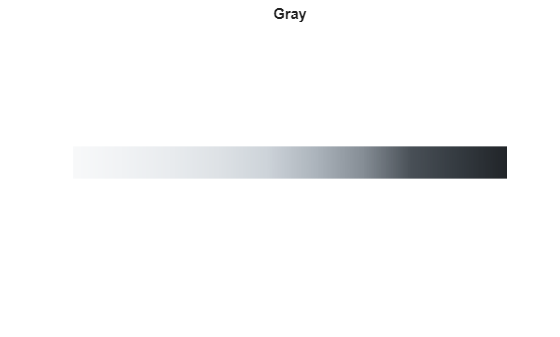

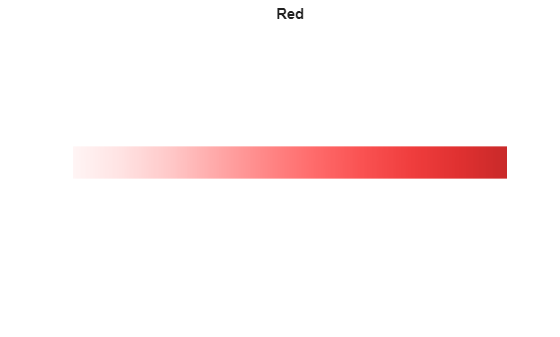

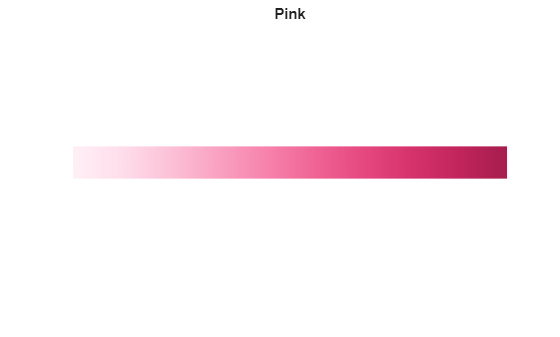

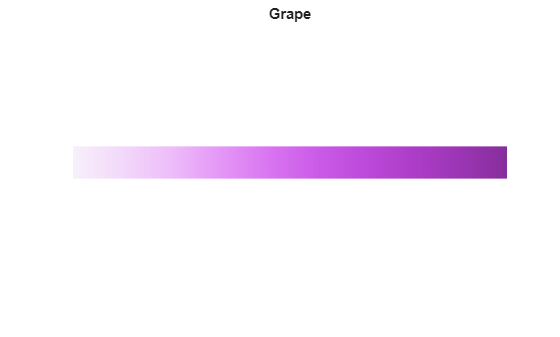

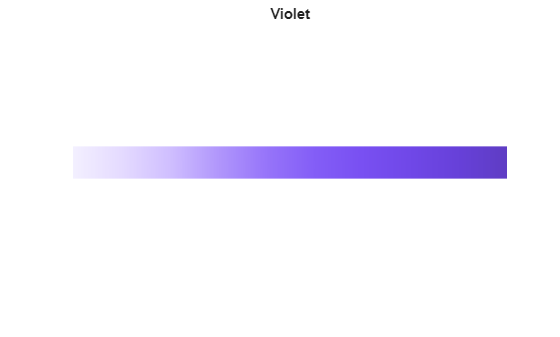

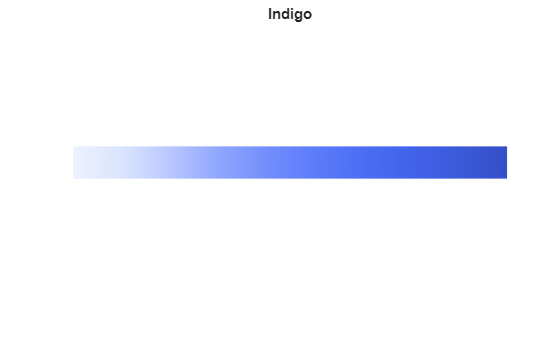

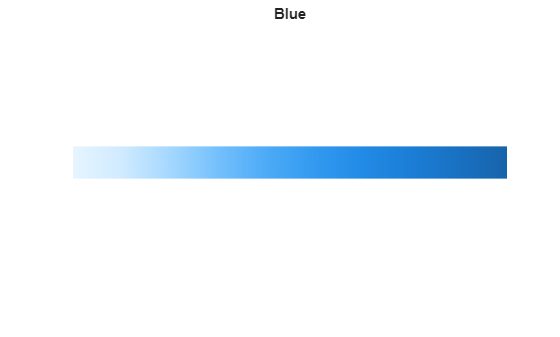

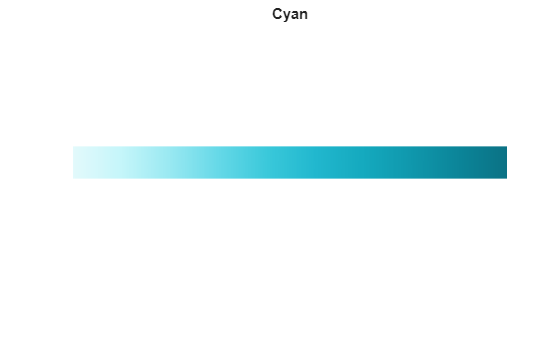

% 使用 pcolor 绘制颜色条
C = repmat(1:256,20,1);
for idx = 1:width(tb)
    figure;
    pcolor(C,EdgeColor="none");
    colormap(gca,RGBCell{idx})
    title(keys(idx))
    axis equal
    axis off
end



function RGBCell = hex_to_rgb(hex_color)  
arguments (Input)
    hex_color (:,:) string
end

arguments (Output)
        RGBCell (1,:) cell
end

[rows,cols] = size(hex_color);
hex_color = extractAfter(hex_color,"#");
RGB = arrayfun(@hex2rgb,hex_color,UniformOutput=false);
RGB = cell2mat(RGB);

numColorScaled = 256; % 256 scaled colors
RGB = interp1(linspace(0,1,rows)',RGB,linspace(0,1,numColorScaled))/(numColorScaled-1);
RGBCell = mat2cell(RGB,numColorScaled,3*ones(1,cols));
end  


function RGB = hex2rgb(hexRGB)
hexRGB = char(hexRGB);
r = hexRGB(1:2);
g = hexRGB(3:4);
b = hexRGB(5:6);

R = hex2dec(r);
G = hex2dec(g);
B = hex2dec(b);

RGB = [R,G,B];
end